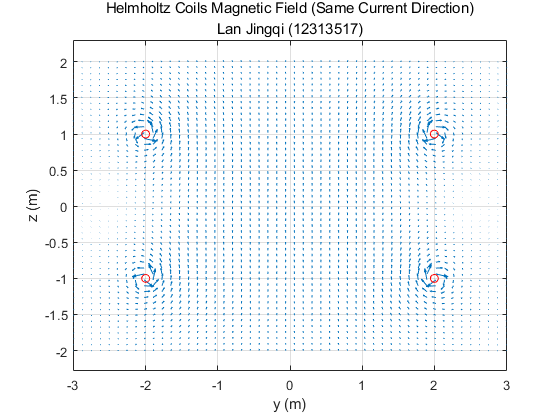

% case1：亥姆霍兹线圈（两线圈电流方向相同）
a = 2;          % 线圈半径 (m)
I = 500;        % 电流强度 (A)
d = 2;          % 两线圈间距 (m)
N = 50;         % 每个线圈的电流元数量
N_length = 2 * pi * a / N;  % 每个电流元长度 (m)
N_angle = linspace(0, 2*pi, N);  % 电流元角度分布

ym = 3;         % y轴采样范围 (m)
zm = 2;         % z轴采样范围 (m)
sample_y = 50;  % y轴采样点数
sample_z = 50;  % z轴采样点数
y = linspace(-ym, ym, sample_y);
z = linspace(-zm, zm, sample_z);

Hy_total = zeros(sample_y, sample_z);
Hz_total = zeros(sample_y, sample_z);

% 计算case1磁场（两线圈电流同向）
for i = 1:sample_y
    for j = 1:sample_z
        P = [0, y(i), z(j)];  % 场点（yz平面，x=0）
        for S_z = [-d/2, d/2]  % 两个线圈的z坐标
            for k = 1:N
                angle = N_angle(k);
                S = [a * cos(angle), a * sin(angle), S_z];  % 电流元坐标
                dl = [-N_length * sin(angle), N_length * cos(angle), 0];  % 电流元矢量
                R = P - S;  % 场点到电流元的矢量
                R_norm = norm(R);
                if R_norm < 1e-6  % 避免场点与电流元重合（除以零）
                    continue;
                end
                dH = cross(I .* dl, R) / (4 * pi * R_norm^3);  % 毕奥-萨伐尔定律
                Hy_total(i,j) = Hy_total(i,j) + dH(2);  % 累加y方向磁场
                Hz_total(i,j) = Hz_total(i,j) + dH(3);  % 累加z方向磁场
            end
        end
    end
end

H = sqrt(Hy_total.^2 + Hz_total.^2);  % 磁场强度大小
[mesh_y, mesh_z] = meshgrid(y, z);    % 网格坐标

% 图1：磁场矢量图（修正转置，确保坐标匹配）
figure;
quiver(mesh_y, mesh_z, Hy_total.', Hz_total.', 'AutoScaleFactor', 1.2);
xlabel('y (m)');
ylabel('z (m)');
title({'Helmholtz Coils Magnetic Field (Same Current Direction)', 'Lan Jingqi (12313517)'});
axis equal;
grid on;
hold on;
% 绘制线圈端点（统一颜色，区分线圈位置）
plot([a, -a, a, -a], [d/2, d/2, -d/2, -d/2], 'ro', 'MarkerSize', 6);
hold off;

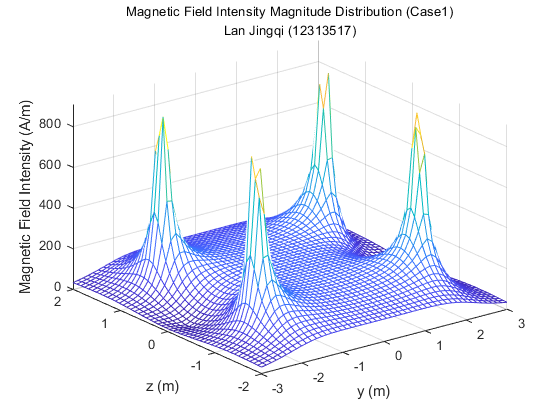


% 图2：磁场强度3D分布图（修正z轴范围与采样一致）
figure;
mesh(mesh_y, mesh_z, H.');  % 转置H，匹配网格维度
axis([-3, 3, -2, 2, 0, max(H(:))]);
xlabel('y (m)');
ylabel('z (m)');
zlabel('Magnetic Field Intensity (A/m)');
title({'Magnetic Field Intensity Magnitude Distribution (Case1)', 'Lan Jingqi (12313517)'}, 'FontSize', 10);

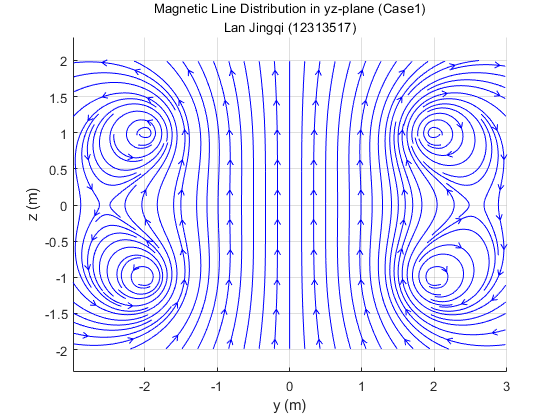


% 图3：磁场流线图
figure;
streamslice(mesh_y, mesh_z, Hy_total.', Hz_total.', 2);
title({'Magnetic Line Distribution in yz-plane (Case1)', 'Lan Jingqi (12313517)'}, 'FontSize', 10);
xlabel('y (m)');
ylabel('z (m)');
axis equal;
grid on;

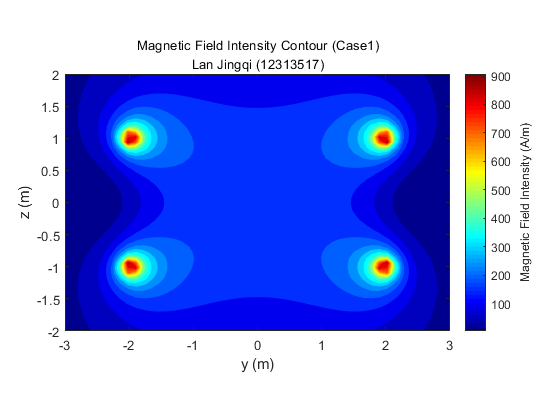


% 图4：磁场等高线图（核心修复：H_magnitude→H，修正转置）
figure;
levels = linspace(min(H(:)), max(H(:)), 20);
% 绘制等高线图并设置面透明度
[~, h] = contourf(mesh_y, mesh_z, H.', levels, 'LineColor', 'none');
colormap jet; % 保持配色一致
fc = get(h, 'FaceColor'); % 获取当前面颜色
set(h, 'FaceColor', [fc(1) fc(2) fc(3) 0.85]); % 设置透明度为0.85
cb = colorbar;
ylabel(cb, 'Magnetic Field Intensity (A/m)');
title({'Magnetic Field Intensity Contour (Case1)', 'Lan Jingqi (12313517)'}, 'FontSize', 10);
xlabel('y (m)');
ylabel('z (m)');
axis equal;

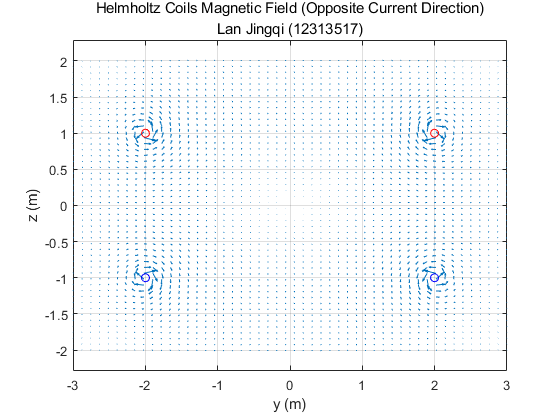


% -------------------------------------------------------------------------
% case2：亥姆霍兹线圈（两线圈电流方向相反）
% 重新初始化变量，避免与case1冲突
Hy_total2 = zeros(sample_y, sample_z);
Hz_total2 = zeros(sample_y, sample_z);

% 计算case2磁场（下线圈电流反向，上线圈正向）
for i = 1:sample_y
    for j = 1:sample_z
        P = [0, y(i), z(j)];
        
        % 下线圈（z=-d/2）：电流反向
        S_z = -d/2;
        for k = 1:N
            angle = N_angle(k);
            S = [a * cos(angle), a * sin(angle), S_z];
            dl = [-N_length * sin(angle), N_length * cos(angle), 0];
            R = P - S;
            R_norm = norm(R);
            if R_norm < 1e-6
                continue;
            end
            dH = cross(-I .* dl, R) / (4 * pi * R_norm^3);  % 电流反向：-I
            Hy_total2(i,j) = Hy_total2(i,j) + dH(2);
            Hz_total2(i,j) = Hz_total2(i,j) + dH(3);
        end
        
        % 上线圈（z=d/2）：电流正向
        S_z = d/2;
        for k = 1:N
            angle = N_angle(k);
            S = [a * cos(angle), a * sin(angle), S_z];
            dl = [-N_length * sin(angle), N_length * cos(angle), 0];
            R = P - S;
            R_norm = norm(R);
            if R_norm < 1e-6
                continue;
            end
            dH = cross(I .* dl, R) / (4 * pi * R_norm^3);
            Hy_total2(i,j) = Hy_total2(i,j) + dH(2);
            Hz_total2(i,j) = Hz_total2(i,j) + dH(3);
        end
    end
end

H2 = sqrt(Hy_total2.^2 + Hz_total2.^2);

% 图5：case2磁场矢量图
figure;
quiver(mesh_y, mesh_z, Hy_total2.', Hz_total2.', 'AutoScaleFactor', 1.2);
xlabel('y (m)');
ylabel('z (m)');
title({'Helmholtz Coils Magnetic Field (Opposite Current Direction)', 'Lan Jingqi (12313517)'});
axis equal;
grid on;
hold on;
plot([a, -a], [d/2, d/2], 'ro', [a, -a], [-d/2, -d/2], 'bo', 'MarkerSize', 6);  % 红：正向线圈，蓝：反向线圈
hold off;

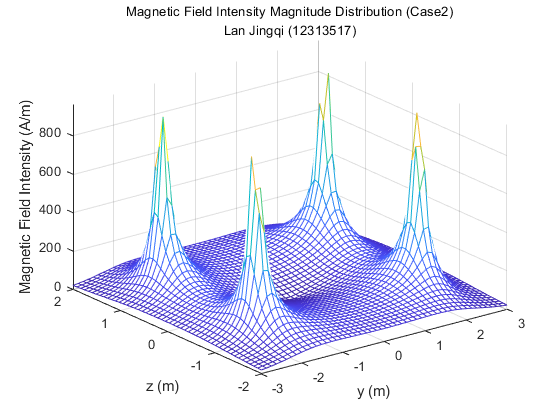


% 图6：case2磁场强度3D分布图
figure;
mesh(mesh_y, mesh_z, H2.');
axis([-3, 3, -2, 2, 0, max(H2(:))]);
xlabel('y (m)');
ylabel('z (m)');
zlabel('Magnetic Field Intensity (A/m)');
title({'Magnetic Field Intensity Magnitude Distribution (Case2)', 'Lan Jingqi (12313517)'}, 'FontSize', 10);

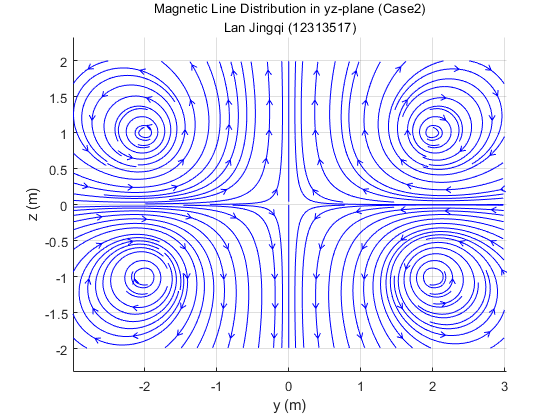


% 图7：case2磁场流线图
figure;
streamslice(mesh_y, mesh_z, Hy_total2.', Hz_total2.', 2);
title({'Magnetic Line Distribution in yz-plane (Case2)', 'Lan Jingqi (12313517)'}, 'FontSize', 10);
xlabel('y (m)');
ylabel('z (m)');
axis equal;
grid on;

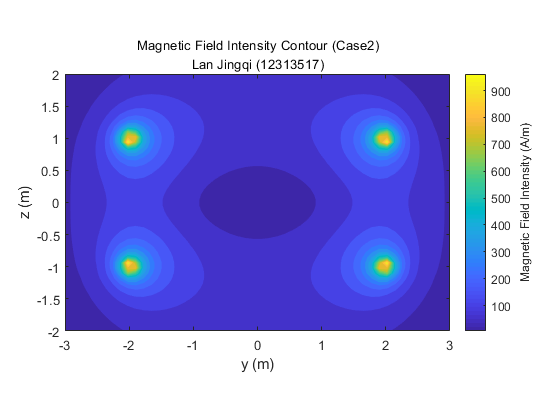


% 图8：case2磁场等高线图（修复变量名和转置）
figure;
levels = linspace(min(H2(:)), max(H2(:)), 20);
[~, h] = contourf(mesh_y, mesh_z, H2.', levels, 'LineColor', 'none');
cb = colorbar;
ylabel(cb, 'Magnetic Field Intensity (A/m)');

% 实现半透明效果（替代FaceAlpha）
fc = get(h, 'FaceColor'); % 获取当前面颜色
set(h, 'FaceColor', [fc(1) fc(2) fc(3) 0.85]); % 最后一个值为透明度（0-1）

title({'Magnetic Field Intensity Contour (Case2)', 'Lan Jingqi (12313517)'}, 'FontSize', 10);
xlabel('y (m)');
ylabel('z (m)');
axis equal;